## **Introduction to Bio-Informatics**

# **Assignment 2: Sequence alignment** 

**Chiara Paglioni (i6249782)**

Another friend of Peter’s studies unicellular microalgae (symbiodinium necroappetens) which also have a RING1 protein, but it is much longer than the human version.  The accession number of this protein is CAE7901930. How close is the algae version to the human protein?  

**Retrieve data from gene bank:**

% Human genome
humanData = getgenpept('CAA78389', 'SequenceOnly', true)

humanData = 'MDGTEIAVSPRSLHSELMCPICLDMLKNTMTTKECLHRFCSDCIVTALRSGNKECPTCRKKLVSKRSLRPDPNFDALISKIYPSREEYEAHQDRVLIRLSRLHNQQALSSSIEEGLRMQAMHRAQRVRRPIPGSDQTTTMSGGEGEPGEGEGDGEDVSSDSAPDSAPGPAPKRPRGGGAGGSSVGTGGGGTGGVGGGAGSEDSGDRGGTLGGGTLGPPSPPGAPSPPEPGGEIELVFRPHPLLVEKGEYCQTRYVKTTGNATVDHLSKYLALRIALERRQQQEAGEPGGPGGGASDTGGPDGCGGEGGGAGGGDGPEEPALPSLEGVSEKQYTIYIAPGGGAFTTLNGSLTLELVNEKFWKVSRPLELCYAPTKDPK'

% Algae genome
algaeData = getgenpept('CAE7901930', 'SequenceOnly', true)

algaeData = 'MASFAPLRRSRGLALLVLSLPLCCFVSAWGTARGRRVEYQARHAAPEPAEPELASPAWEESAQVVLEIVEDSTKEDALDWLQAGYAWTAKSRRFWRKLRSPMPPEPEAVRRTARWLQDKGLAQKAWVRRFPEVLGLSVEDLEEGRSTAPSYLKSEDTYNKAIKSNPTLLGKNYDCLQEHESCQGRCSRCWNTTDAEQSEQYTLCGCLGFLGGLSILENIGPLKLRAGSSSGTVSGLSSISGSSYQAAMKHALLLLALPAHATQISTEDPALLSDEQASLREEDEWRPSAQATFPRPSYGNGWSPWSGNPGSLPGGPAAHLPYQAVPRVPAPPPAGTFPKVAVSSAASGAGPNNLKEAEAETKKFFEIEEMVAKETGLPLNSSEAAQKEEEEKAEAKEVEEEEEEERFDALYAGIALVILLAAGGTFYFHRWSQDKPKPGEALGAAAPSSPEADPKAPGPAEAEAKAATGRMKRKLLQLQVLILLSPLSEGPLSCQWGERWPLPDPSPSEGAMGKKRKAEFEPPPVNLDALPPLEEGILRFEFTLEEKGALGVRFSGGSPPMILSVAPDSFASKKGIPVNYEVHAINGLALVQQNQQRVMHFLKSRPVVLDVRPLGWKPPEKMKELKRRQQQEEAEQKAKMAVEKKRREQDGWKVEMHSEEIQQFNADVRQVFSSVFSACTWLSKPNERSPQLVPQKPLPLGQNQLRVCEELERLGLLKASPLPSPFVVAFHELLSSPVGGECSCGAMGDLPFSLAALLNSGAGALGPAREGGTITLLTLPGRGLVGAAITPSGSEPGFPLPLGLLQSLGGQVSRVPVAAEEDAADALGGIMRMMMEQMAQIAMQRSMEESGPKVPPASERVRDALPRVVVTKEDLLDATNSKCSVCLEDYRPGVRATRMLCGHLFCTGCIREWLREANTCPVCRYELATDCEDFESGRRTRMSGRIVRLRAAELRMLRISELRRLMDALGVSGEGCLERADLVRHLE

**Plot the comparison of the two DNA sequences:**

Firstly, the two genomes are compared by using **seqdotplot**. This function displays the matches of the two sequences: 30905. In particular, in the figure it is possible to visualize where the two genomes overlap, i.e. in which regions they share the same bases. Moreover, since no diagonal line clearly appears in the plot, a local search of the DNAs is a better approach to compare the two sequences.

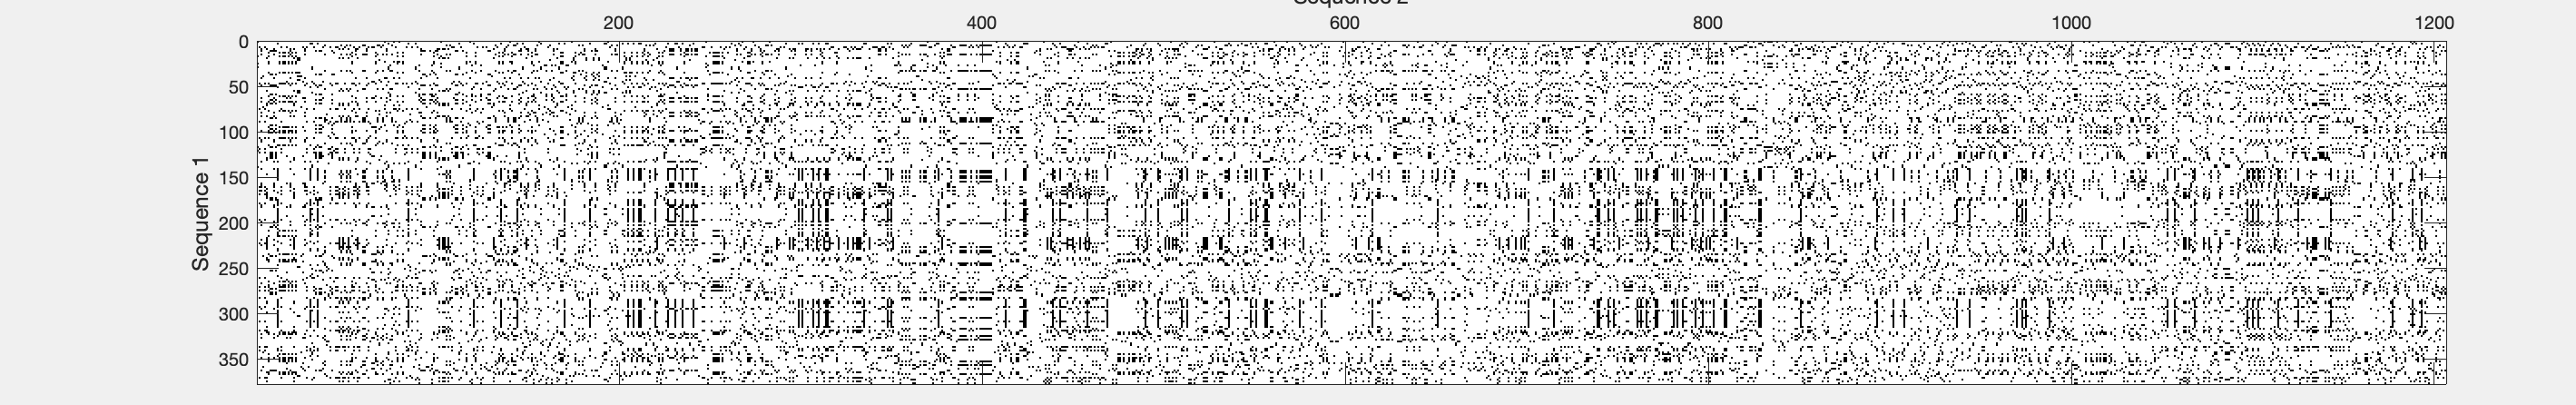

figure;
matches = seqdotplot(humanData, algaeData);

matches

matches = 30905

**Sequence alignments:**

Both global and local alignments are performed on the human and algae genomes in order to determine which one is the optimal alignment. The following are the result obtained by using the **nwalign** and **swalign** commands respectivelly: 

- **Global** alignment: -1.0216e+03

- **Local** alignment: 53.2000

The scores obtained from the two alignments also tell us that the local sequence alignment is the optimal one since its score is higher. 

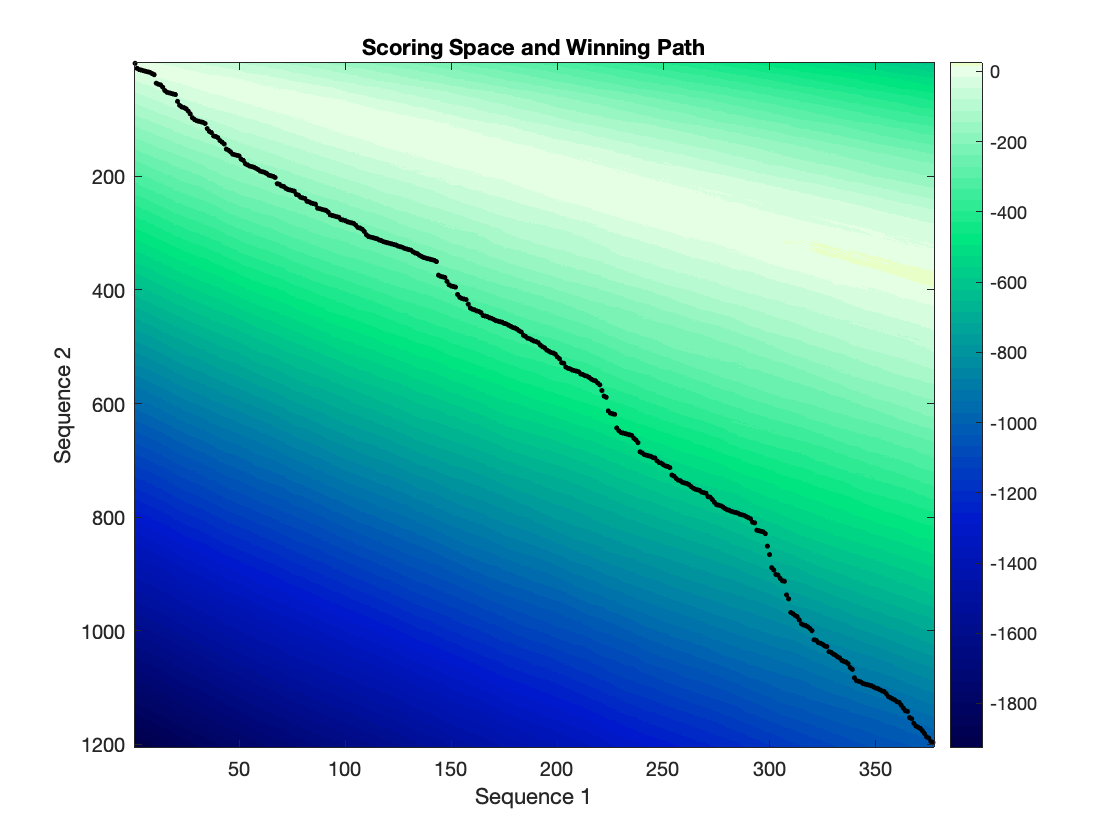

% Global alignment
figure;
[GlobalScore, GlobalAlignment] = nwalign(humanData, algaeData, ScoringMatrix='blosum30', ...
    ShowScore=true);

GlobalScore

GlobalScore = -1.0216e+03

GlobalAlignment

GlobalAlignment = 3×1206 char array
    'M--------D-GTEIAV-S-P--------------R-SL---H-----S--ELMCP-----------I------C--LD-M---L----K------N--T-MTTK-E--------C----L-H-----RF-C----S--D--C--------I-V--T---ALRS-----G-N-----K-E-CPT-C-R--KKL-V--SKR-S----------LR--PD--P-NFDA-----LI---SKI----YP-SRE------EYEAH--Q----DRVLI---RLS-RLHN--Q---QA-L---S-----S--SIEEG-LR-MQAMHRA-QRV-RRPI--P-GS--D-Q-TTTMSG-G-----------------------E-GEP------G-----E-GEG------------D----G-EDV-------S------S-DS-AP-D----SAP-GP-A-PKRP-RG-G-G-AG-G--S-S-----V-G--TG-G-GG-T---G--G-V---G-G-GA-G----S--E------DS------G-DR-GGTL---GG-GT-L--G-PP---S--P---------P---------G-A-----------------------P---SPP-----------------------E----P--GGEIEL----V--F----R---------------P-H--PLLV-EK----G--EY--C-QT-R------------Y-V---K--TT--GNA-T--V--D-HLS--KYL-----AL---R----I---ALE-R--R-QQ-QEAG-EPG-G-P-G-----GG------------ASDT--G---------------------G--------------P----------------------D---G-------CG-----G---EG-----------------------G------G---------------

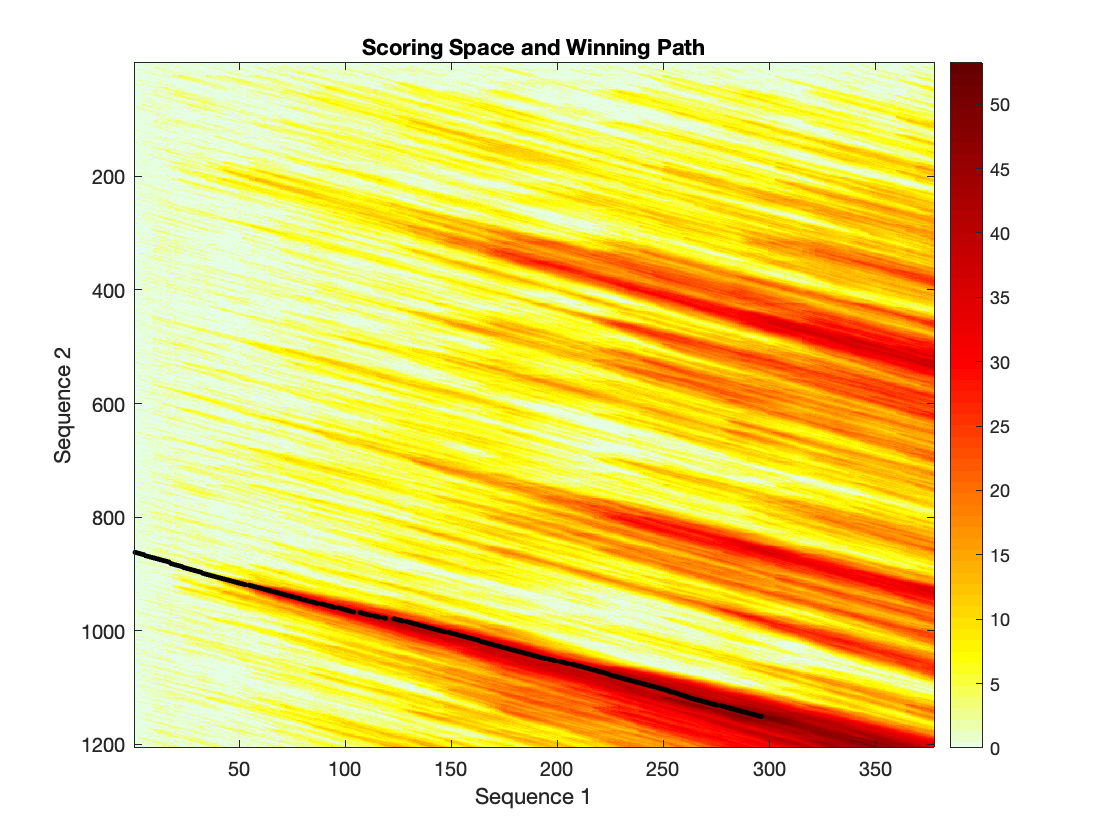

% Local alignment 
figure;
[LocalScore, LocalAlignment] = swalign(humanData, algaeData, ScoringMatrix='blosum30', ...
    Showscore=true);

LocalScore

LocalScore = 53.2000

LocalAlignment

LocalAlignment = 3×306 char array
    'MDGTE-IAVSPRSLHSEL--MCPICL-DMLKNTMTT-KECLHRFCSDCIVTALRSGNKECPTCRKKLVSKRSLRPDPNFDALISKIYPSREEYEAHQDRVLIRLSRLHNQQALSSSIEEGLRMQAMHRAQRVRRPIPGSDQTTTMSGGEGEPGEGEGDGEDVSSDSAP-DSAPGPAPKRPRGGGAGGSSVGTGGGGTGGVGGGAGSEDSGDRGGTLGGGTLGPPSPPGAP-SPPEPGGEIELVFRPHPLLVEKGEYCQT-RYVKT-TGNA-TVDHLSKYLALRIALERRQQQEAGEPGGPGGGASD'
    ':|::: ::|:: :| :::  :| :|| |  :::::| : | | ||: ||   ||::|  ||:|| :|::: :  ::     : ::|:  |:: |    |:   | ||::  ||: |  ||: ::   ||  | |:::|:  : ::   ::|: :   | :|::  : |   :  : :: |    :  |:      :: :: : ||    |: : |    : | :  |: | :::||:  :  :| | :   |:||  :: :: :| :| :  ::  ::  | | | |  :::    ||::: :::|'
    'RDALPRVVVTKEDLLDATNSKCSVCLEDYRPGVRATRMLCGHLFCTGCIREWLREANT-CPVCRYELATDCEDFESGRRTRMSGRIVRLRAA-ELRMLRI-SELRRLMD--ALGVSG-EGC-LE---RADLV-RHLEGAPDVEVAPELSAEK-KFRYDLQDLEQLDLPLLRNLMERHRVPFDLEEDLSEDDERRVALRSF-ADAG-WMRGA-SKTPPKPSEGAKQMPARPENTTEPAQTTTAAFVPSTDAGESGESGESEMRSETPSGESCEAKSRAAGKAARPA-EPPPARRRPRPGAKAEAKAD'


The *Blosum30* scoring matrix is used in the two alignment in order to have a better visualization of the RING1 protein. Such protein can be observed as a black line in the two plots. In the end, comparing the two figures, it is posssible to conclude that local alignment is better since its scores are higher than the global ones.

**Statistical analysis of alignments: **

Now, to check how close the algae version is to the human protein, the results previously obtained by the two alignments are compared to a random sequence of DNA. The following are the steps performed to mesure the similarity of the two genes: 

- Generate random sequences based on the distribution of the human genome

- Determine the optimal (local) alignments of the algae genome with these random sequences

- Plot a histogram of the scores of these optimal alignments and show the observed score in the plot

- Calculate a p-value based on how often the random sequences can be better aligned than the real sequence

% Show properties of humanData
figure; 
distribution_human = aacount(humanData)

distribution_human = struct with fields:
    A: 23
    R: 24
    N: 7
    D: 18
    C: 10
    Q: 11
    E: 31
    G: 63
    H: 7
    I: 12
    L: 31
    K: 16
    M: 7
    F: 5
    P: 34
    S: 31
    T: 23
    W: 1
    Y: 8
    V: 15


% Generate sequences based on distribution of humanData
n = 1000;       % Number of sequences
count = 0;      % Counter used to calculate p-value 
random_genes = string(zeros(1,n));
random_scores = zeros(1,n);

for i = 1:n
    % Get random sequence based on distribution of humanData
    random_gene = randseq(length(humanData), 'FromStructure', distribution_human);     
    random_genes(i) = random_gene;

    % Compute local alignment with random sequence
    random_scores(i) = swalign(random_gene, algaeData,  ScoringMatrix='blosum30');

    % Compare random score to the local score
    if random_scores(i) > LocalScore
        count = count + 1; 
    end     
end    

random_genes

random_genes = 1×1000 string array
  Columns 1 through 399

    "IPLDRPEHLGLAWLEYE…"    "GDGPPPAHLSRIEPGGR…"    "GELLQSGAAGEPDPESD…"    "PGEGAVFSEIARDGEFG…"    "LKAVEGIVNGYGFRAPT…"    "SEKAKNSGGHAGEDGSH…"    "GDSFPDTGLPRQGQSGR…"    "IQDSIHQEAEMHRGARP…"    "TSMAEPELNPGDPALGK…"    "PRYWGPKMGGEVTVASL…"    "GLSEGDDDPTTGSGLGG…"    "STEPPGGGSSEESSDDA…"    "KCGLEAARRTASTGESR…"    "VTTQALIKGLVLPEMLG…"    "GAAFIIMTGTAVLMTRE…"    "EGPKGMTVDCPSGEEES…"    "RPFGCGCYRAGGGSIGS…"    "PSLRAGTLGTQATSDEK…"    "SREGPCPKQGATVVRLE…"    "DLKSHLTMIGNGALGPK…"    "KLVRARGGPVGIELGAG…"    "AIPIYGRGMLVEGAQIP…"    "GPCGTKGESSELGGRAS…"    "AGERQGIGCLEDGVMFM…"    "GKVTDPKTQSPMRLKAL…"    "PCPLFGEQGQTLCAGPS…"    "KSDLIPGSDRRTGSIKQ…"    "IGGRVRIGLSSERLIMV…"    "GIGTSSRLQEPVAPLYS…"    "DARVHVTIDKWQGMDGK…"    "KMGIRLECAIAIETLLP…"    "ALKGVGCLGHERVSGPM…"    "PGASLHPGVTGQIVCEN…"    "GQGVDGPRDTDGTKPAN…"    "DKSKPTGGSKKSKESSG…"    "KGGTLPPHYGATGPGHS…"    "PPSPGPVAGQHKDGPGP…"    "TQSTGGPVSYLDNSITR…"    "YGPGYETMSAGGDLHMG…"    

random_scores

random_scores =    40.4000   44.6000   36.2000   39.8000   45.0000   41.0000   41.4000   41.4000   47.8000   40.8000   40.4000   43.6000   41.6000   43.0000   41.2000   40.0000   41.2000   44.2000   39.6000   38.4000   44.2000   44.4000   45.8000   44.0000   43.4000   45.0000   43.0000   38.8000   43.6000   37.8000   46.6000   39.2000   38.2000   38.0000   44.6000   36.8000   43.2000   43.4000   35.8000   34.8000   44.8000   43.2000   40.8000   41.8000   42.6000   43.8000   36.8000   42.2000   40.8000   40.4000


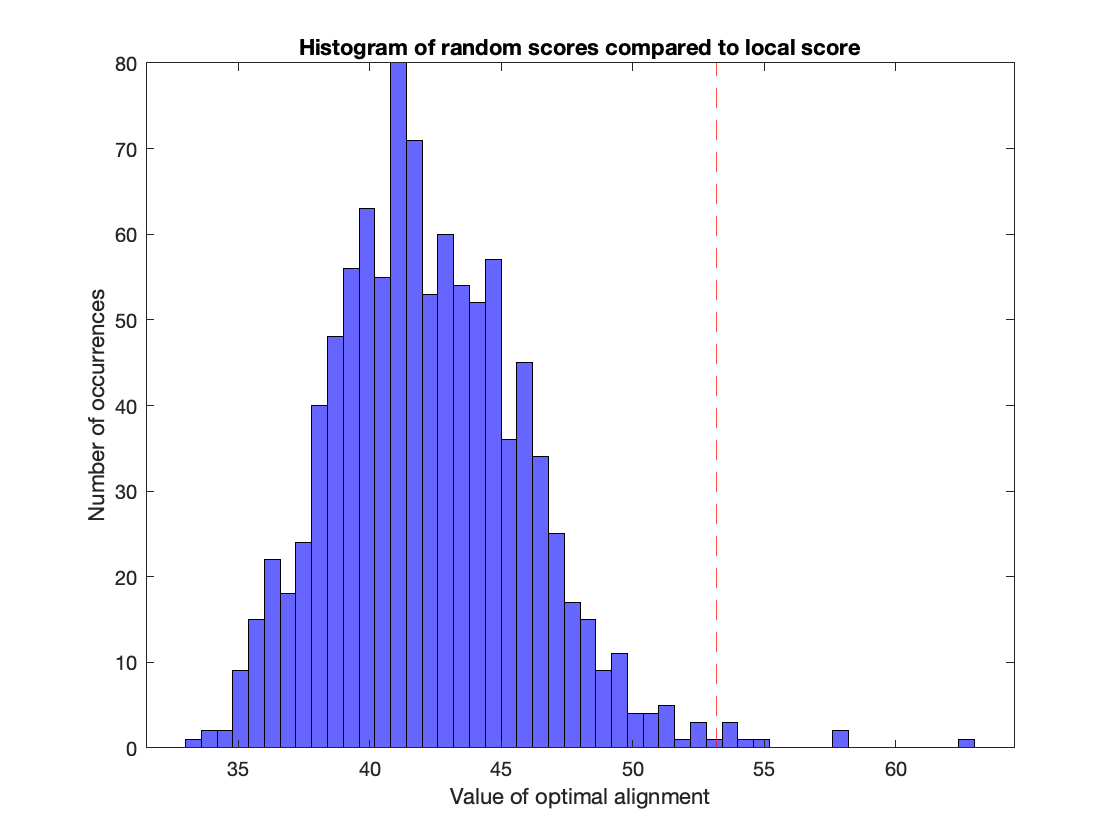

% Plot scores compared to the original one
figure;
random_hist = histogram(random_scores, 50);
random_hist.FaceColor = 'blue';
title('Histogram of random scores compared to local score')
xlabel('Value of optimal alignment')
ylabel('Number of occurrences')

hold on; 
xline(LocalScore, '--r')

The histogram shows:

- **Blue bars** = local scores of randomly generated strings using permutation of the human genome 

- **Red line** = local score of the orginal sequence of the human genome

From the plot, it appears that the local scores of the randomly generated strings are quite similar to the original value of the local alignment. Given that, it is clear that the algae and human sequences are similar to each other.

Finally, the p-value is computed is order to determine how similar the two sequences are. The p value is computed as follows: 

***c**** = number of random local scores smaller than the original local score*

***n**** = number of simulations*

***p**** = c/n*

% Calculate p-value
% Compare p value to p (0.5) to check whether it is significant or not
count

count = 8

p = count/n

p = 0.0080

Since the sequences are randomly generated, the value of p changes at every run. However, p is always very small and close to 0. This happens because the value of c is very small, meaning that there are very few occurrences of random local scores higher than the original one. 

To sum up, the results obtained are significant since the value of p is always smaller than 0.5. Given that, the null hypothesis is rejected and it is possible to conclude that the algae and human genome are close to each other.  